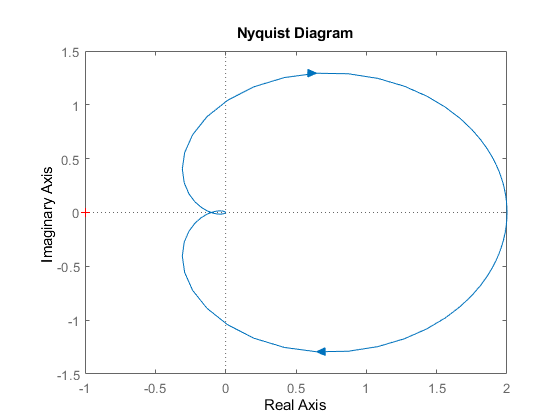

T1=10;T2=4;T3=1;
A=2;

Wo= tf(A, conv(conv([T1 1],[T2 1]),[T3 1]));

figure(1); nyquist(Wo);

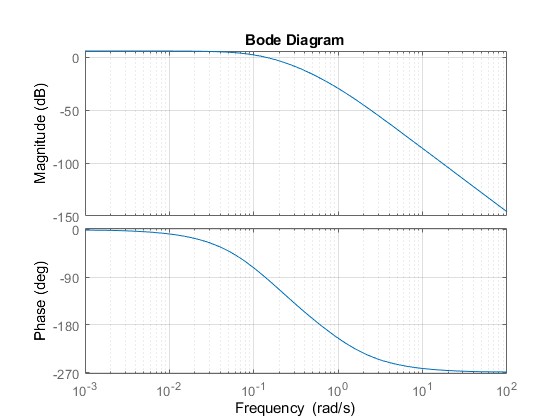

figure(2); bode(Wo); grid on;

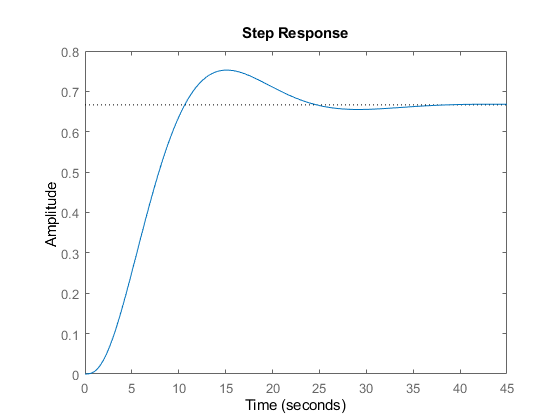

Wcl=feedback(Wo, 1, -1);
figure(3); step(Wcl);

Stabil?

step(Wcl);

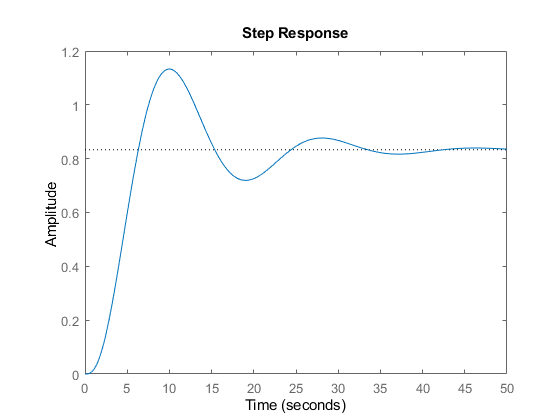

T1=10;T2=4;T3=1;
A=5;

Wo= tf(A, conv(conv([T1 1],[T2 1]),[T3 1]));
Wcl=feedback(Wo, 1, -1);

step(Wcl);

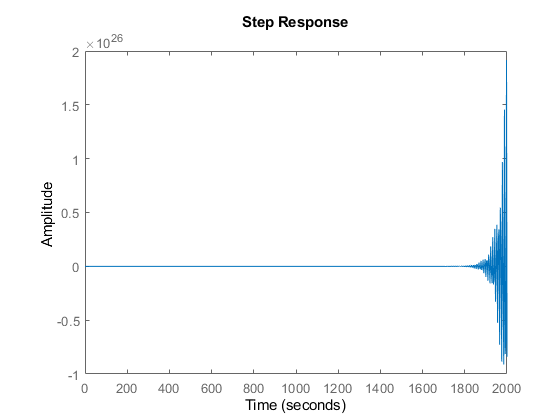

T1=10;T2=4;T3=1;
A=25;

Wo= tf(A, conv(conv([T1 1],[T2 1]),[T3 1]));
Wcl=feedback(Wo, 1, -1);
step(Wcl);

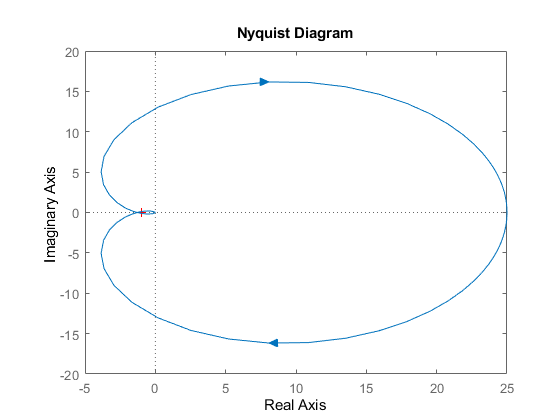

nyquist(Wo);

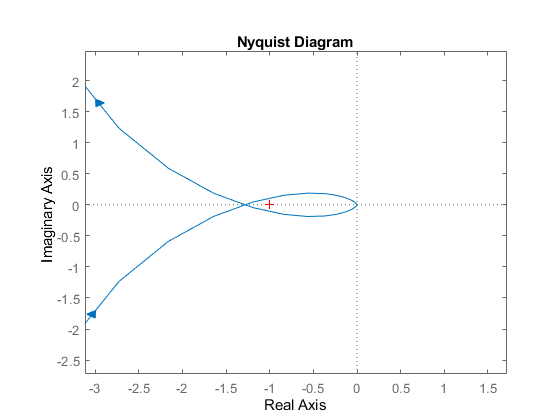


h = nyquistplot(Wo); 
p = getoptions(h);
p.XLim = {[-3.11611, 1.71801]};
p.YLim = {[-2.72446, 2.47678]};
setoptions(h,p);

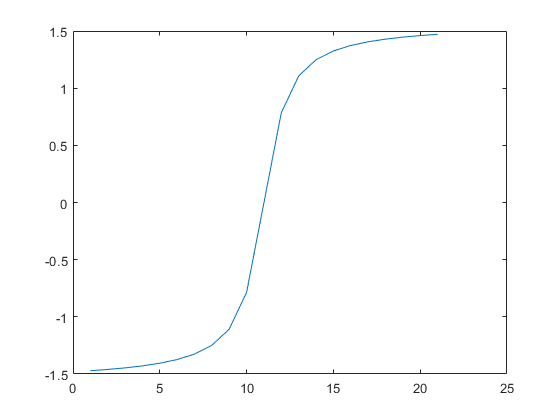

plot(atan(-10:1:10));

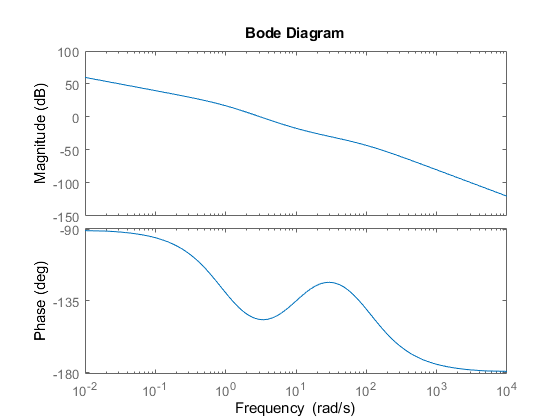


Wo=tf(100*[1 10], conv([1 1 0], [1 100]));
bode(Wo);

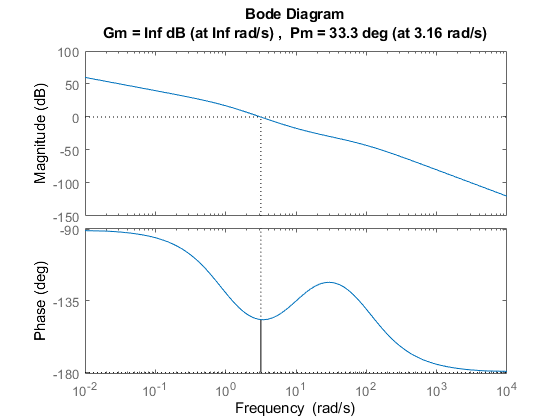

margin(Wo);

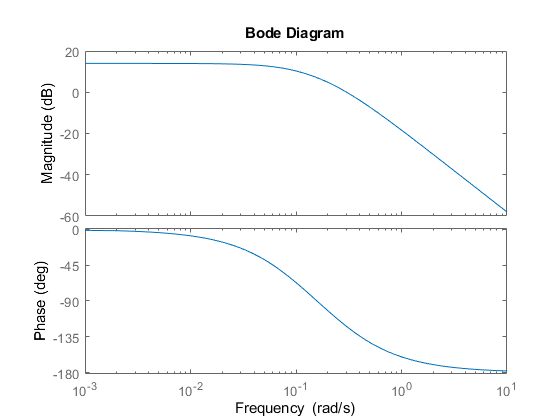

clear;clc;

Wp=tf(5, conv([10 1],[4 1]));
Ap = 1;
Wc = Ap;
Wo=Wp*Wc;
bode(Wo);

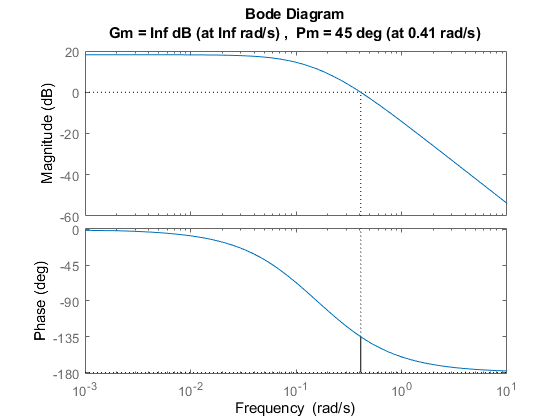

A1=-4.21;
Ap=10^(-A1/20);
Wc=Ap;
Wo=Wp*Wc;
margin(Wo);